for data_index = 1:20
    folderPath = sprintf('C:\\Users\\Lenovo\\Desktop\\Project 2\\rawData\\data_%d\\', data_index);
    addpath(folderPath);
    filename = sprintf('data_%d.mat', data_index); 
    load(filename);

Task1

    %暂时先只处理0.01s
    seq_sur1=seq_sur(1:(length(seq_sur)/50));
    seq_ref1=seq_ref(1:(length(seq_sur)/50));
    duration1=0.01;

    %reference signal:freq-domain
    drawSpectrum(seq_ref1,f_s)
    drawDDCSpectrum(seq_ref1,f_s)
    AfterLPFSpectrum(seq_ref1,f_s);

    %reference signal:time-domain
    TimePlotting(seq_ref1,f_s,"Reference signal (raw)")
    DDC_TimePlotting(seq_ref1,f_s,"Reference signal (after DDC)")
    AfterLPF_TimePlotting(seq_ref1,f_s,"Reference signal (after LPF)", "Reference Signal",data_index)

    %surveillance signal:freq-domain
    drawSpectrum(seq_sur1,f_s)
    drawDDCSpectrum(seq_sur1,f_s)
    AfterLPFSpectrum(seq_sur1,f_s);

    %surveillance signal:time-domain
    TimePlotting(seq_sur1,f_s,"Surveillance signal (raw)")
    DDC_TimePlotting(seq_sur1,f_s,"Surveillance signal (after DDC)")
    AfterLPF_TimePlotting(seq_sur1,f_s,"Surveillance signal (after LPF)", "Surveillance Signal",data_index)

Task2

    seq_ref_after_LPF=AfterLPF_Timeseries(seq_ref,f_s);
    seq_sur_after_LPF=AfterLPF_Timeseries(seq_sur,f_s);

    cor_matrix=zeros([7,41]);
    N_tau=0:6;
    f_D=-40:2:40;
    for i=1:1:7
        for j=1:1:41
            seq_sur_cor=[seq_sur_after_LPF,zeros(1,N_tau(i))];
            seq_ref_cor=[zeros(1,N_tau(i)),seq_ref_after_LPF];
            n_spaced=0:length(seq_sur_cor)-1;
            cor_matrix(i,j)=abs(sum(seq_sur_cor.*conj(seq_ref_cor).*exp((-2i*pi*f_D(j)/f_s)*n_spaced)));
        end
    end

    minVal = min(cor_matrix(:));
    maxVal = max(cor_matrix(:));
    
    % 进行 0-1 标准化,3次方加强效果
    matrix_normalized = ((cor_matrix - minVal) / (maxVal - minVal)).^3

    % 使用max函数找到矩阵中的最大元素及其位置
    [maxValue, linearIndex] = max(matrix_normalized(:));
    % 将线性索引转换为行列索引
    disp("max value index")
    [row, col] = ind2sub(size(matrix_normalized), linearIndex)
    cor_max_f_D=(col-1)*2-40
    cor_max_tau=(row-1)*3e8/f_s

    figure
    pcolor(f_D,N_tau*3e8/f_s,matrix_normalized)
    colorbar;
    xlabel("Doppler frequency(Hz)"),ylabel("Range(m)"),yticks([0,12,24,36,48,60,72]);
    Title = sprintf('Range-Doppler Spectrum [%4.1fs: %dm - %dHz]', 0.5*data_index-0.5, cor_max_tau, cor_max_f_D);
    title(Title)

    % 保存图形
    filename = sprintf('Range-Doppler Spectrum data%d.png', data_index)
    saveas(gcf, filename);

end 

matrix_normalized =     0.0012    0.0002    0.0003    0.0003    0.0001    0.0001    0.0001    0.0003    0.0001    0.0019    0.0006    0.0011    0.0000    0.0016    0.0003    0.0013    0.0003    0.0004    0.0004    0.0000    0.0000    0.0000    0.0996    0.0343    0.0161    0.0088    0.0036    0.0001    0.0002    0.0002    0.0002    0.0003    0.0021    0.0007    0.0005    0.0002    0.0005    0.0001    0.0004    0.0009    0.0001
    0.0001    0.0034    0.0020    0.0042    0.0008    0.0018    0.0004    0.0036    0.0017    0.0098    0.0050    0.0003    0.0010    0.0010    0.0022    0.0032    0.0161    0.0085    0.0220    0.0000    0.0000    0.0000    1.0000    0.5048    0.1758    0.0311    0.0320    0.0127    0.0007    0.0001    0.0034    0.0076    0.0042    0.0081    0.0019    0.0009    0.0000    0.0015    0.0021    0.0038    0.0009
    0.0005    0.0003    0.0000    0.0002    0.0006    0.0003    0.0003    0.0002    0.0013    0.0001    0.0001    0.0000    0.0003    0.0000    0.0001    0.00

max value index


row = 2

col = 23

cor_max_f_D = 4

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data1.png'

matrix_normalized =     0.0012    0.0003    0.0003    0.0014    0.0001    0.0003    0.0008    0.0035    0.0008    0.0001    0.0032    0.0074    0.0136    0.0159    0.0244    0.0086    0.0561    0.0819    0.0286    0.0000    0.0000    0.0000    0.0389    0.0433    0.0008    0.0360    0.0648    0.0499    0.0034    0.0007    0.0035    0.0009    0.0001    0.0000    0.0042    0.0001    0.0000    0.0013    0.0004    0.0041    0.0015
    0.0033    0.0027    0.0000    0.0012    0.0000    0.0020    0.0160    0.0087    0.0005    0.0019    0.0195    0.0222    0.0230    0.0127    0.0238    0.0136    0.0425    0.1047    0.0560    0.0000    0.0000    0.0000    0.2018    0.2172    0.1264    0.1170    1.0000    0.2243    0.1832    0.0340    0.0207    0.0005    0.0000    0.0015    0.0032    0.0002    0.0005    0.0034    0.0001    0.0026    0.0030
    0.0009    0.0025    0.0001    0.0001    0.0000    0.0003    0.0038    0.0005    0.0000    0.0018    0.0031    0.0031    0.0030    0.0012    0.0027    0.00

max value index


row = 2

col = 27

cor_max_f_D = 12

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data2.png'

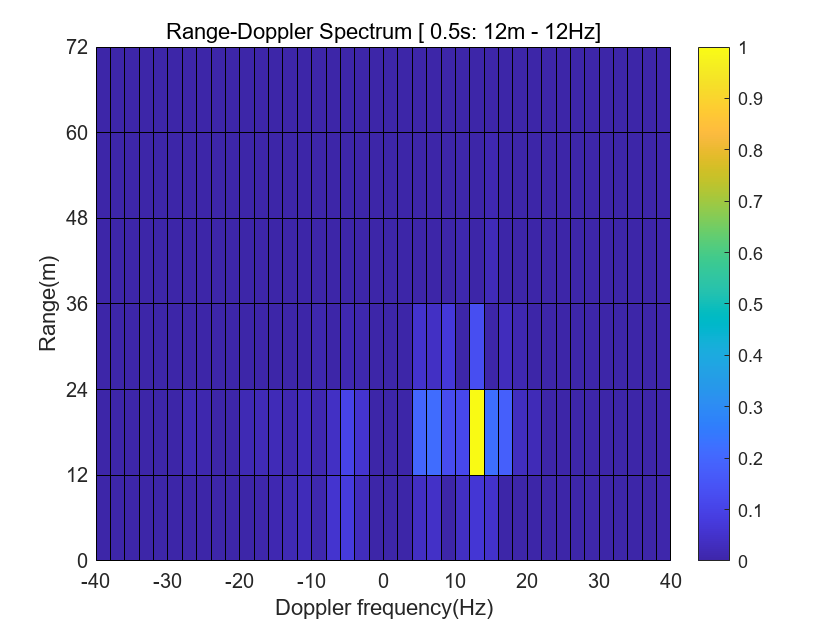

matrix_normalized =     0.0004    0.0025    0.0022    0.0071    0.0048    0.0000    0.0084    0.0008    0.0023    0.0002    0.0161    0.0000    0.0121    0.0057    0.1602    0.0208    0.0101    0.0070    0.0087    0.0000    0.0000    0.0000    0.0047    0.0367    0.0145    0.0003    0.0035    0.0006    0.0057    0.0144    0.0057    0.0004    0.0085    0.0006    0.0094    0.0135    0.0032    0.0012    0.0123    0.0016    0.0000
    0.0056    0.0022    0.0311    0.0085    0.0062    0.0073    0.0371    0.0055    0.0308    0.0078    0.0358    0.0096    0.0970    0.0714    1.0000    0.1080    0.1041    0.1926    0.0019    0.0000    0.0000    0.0000    0.0005    0.2217    0.0630    0.0074    0.3852    0.0002    0.0049    0.1461    0.0037    0.0043    0.1643    0.0312    0.2989    0.0176    0.0147    0.0444    0.0452    0.0035    0.0070
    0.0000    0.0005    0.0066    0.0002    0.0002    0.0060    0.0001    0.0008    0.0022    0.0015    0.0001    0.0046    0.0096    0.0091    0.0305    0.00

max value index


row = 2

col = 15

cor_max_f_D = -12

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data3.png'

matrix_normalized =     0.0003    0.0001    0.0000    0.0001    0.0007    0.0006    0.0018    0.0026    0.0018    0.0017    0.0007    0.0013    0.0075    0.0158    0.0169    0.0079    0.0005    0.0002    0.0016    0.0000    0.0000    0.0000    0.0004    0.0006    0.0017    0.0074    0.0108    0.0039    0.0001    0.0034    0.0001    0.1211    0.0219    0.0000    0.0000    0.0006    0.0012    0.0016    0.0014    0.0004    0.0002
    0.0002    0.0001    0.0005    0.0041    0.0063    0.0073    0.0066    0.0063    0.0077    0.0111    0.0132    0.0119    0.0245    0.0804    0.0988    0.0674    0.0324    0.0163    0.0358    0.0000    0.0000    0.0000    0.0361    0.0248    0.0318    0.0615    0.0930    0.0850    0.0126    0.0282    0.0009    1.0000    0.3139    0.0123    0.0084    0.0074    0.0064    0.0025    0.0015    0.0000    0.0000
    0.0000    0.0000    0.0001    0.0008    0.0008    0.0004    0.0000    0.0000    0.0003    0.0011    0.0026    0.0024    0.0003    0.0024    0.0060    0.00

max value index


row = 2

col = 32

cor_max_f_D = 22

cor_max_tau = 12

filename = 'Range-Doppler Spectrum data4.png'

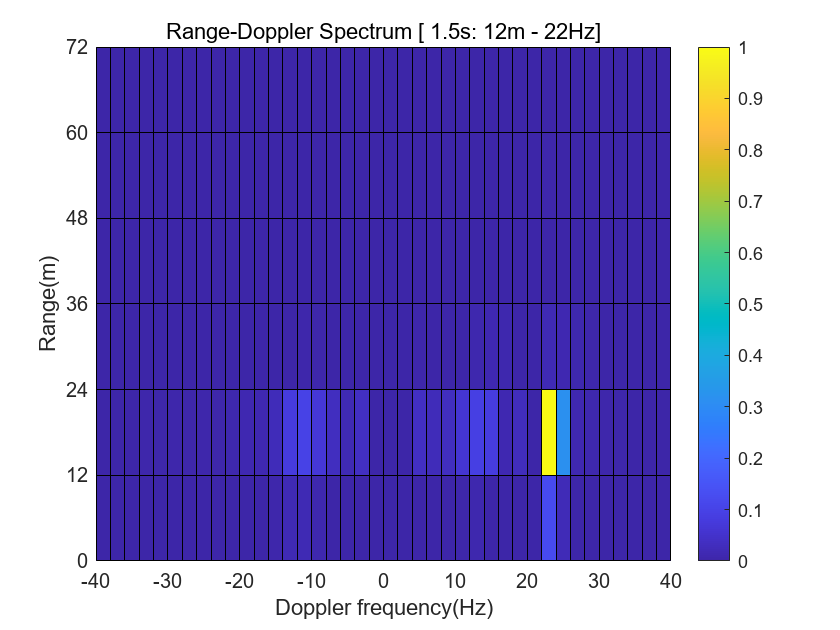

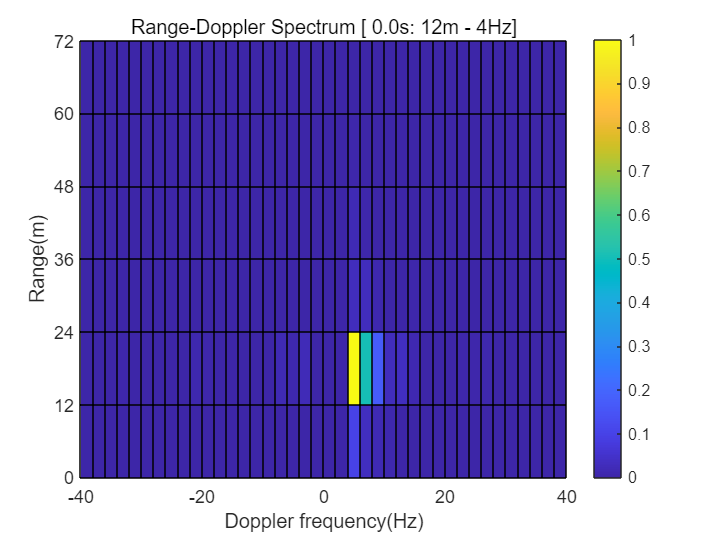

function drawSpectrum(x,fs)
    N=length(x);
    H=fftshift(fft(x));
    f=(-N/2:N/2-1)*fs/N;
    figure,set(gcf, 'Position', [100 100 1000 800])
    subplot(3,2,1),plot(f./10^6,20*log10(abs(H)))
    xlabel("Frequency(MHz)"),ylabel('Amplitude(dB)'),ylim([-80,0])
    title('Spectrum (raw)')

end

function [H,H_filtered]=SpectrumExtraction(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    x=x.*exp(-1j*2*pi*f_ddc*xTime(x,fs));

    %DDC
    H=fftshift(fft(x));
    
    %LPF
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
    H_filtered=fftshift(fft(x_filtered));
end

function drawDDCSpectrum(x,fs)
    [H,~]=SpectrumExtraction(x,fs);

    N=length(x);
    f=(-N/2:N/2-1)*fs/N;
    subplot(3,2,3),plot(f./10^6,20*log10(abs(H)))
    xlabel("Frequency(MHz)"),ylabel('Amplitude(dB)'),ylim([-80,0])
    title('Spectrum (after DDC)')
end

function AfterLPFSpectrum(x,fs)
    [~,H]=SpectrumExtraction(x,fs);

    N=length(x);
    f=(-N/2:N/2-1)*fs/N;
    subplot(3,2,5),plot(f./10^6,20*log10(abs(H)))
    ylabel('Amplitude(dB)'),ylim([-70,0]),xlabel('Frequency(MHz)')
    title('Spectrum (after LPF)')
end

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function TimePlotting(x,fs,Title)
    t=xTime(x,fs);
    subplot(3,2,2),ylim([-4*1e3,4*1e3]),plot(t*1e3,x)
    ylabel("Amplitude"),xlabel("Time(ms)"),ylim([-4*1e-3,4*1e-3])
    title(Title)
end

function DDC_TimePlotting(x,fs,Title)
    f_ddc=-3e6;

    t=xTime(x,fs);
    x=x.*exp(-1j*2*pi*f_ddc*xTime(x,fs));
    subplot(3,2,4),plot(t*1e3,x)
    ylabel("Amplitude"),xlabel("Time(ms)"),ylim([-4*1e-3,4*1e-3]),title(Title)
end

function AfterLPF_TimePlotting(x,fs,Title,Filename,data_index)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);

    x=x.*exp(-1j*2*pi*f_ddc*xTime(x,fs));
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
    subplot(3,2,6),plot(t*1e3,x_filtered);
    ylabel("Amplitude"),xlabel("Time(ms)"),ylim([-4*1e-3,4*1e-3]),title(Title)

    filename=sprintf('%s data%d.png', Filename, data_index);
    saveas(gcf, filename);
end

function x_filtered=AfterLPF_Timeseries(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);

    x=x.*exp(-1j*2*pi*f_ddc*xTime(x,fs));
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
end

%{
function Cor=cor(tau,f_D,y_surv,y_ref,fs)
    zero_compensation =zeros([1,fix(tau*fs)]);
    y_surv_com=[y_surv,zero_compensation];
    y_ref_com=[zero_compensation,y_ref];
    function y=exp_component(n,f_D,fs)
        y=exp((-2i*pi*f_D/fs)*linspace(0,n-1,n));
    end
    Cor=abs(sum(y_surv_com.*conj(y_ref_com).*exp_component(length(y_surv_com),f_D,fs)));
end
%}